We do the second task here, i.e, neutral vs facial expression classification.

Note that we use only the dataset - DATA

% Clear all the previous variables and commands from the workspace
clear variables; clc;

% Split the data into training and testing
[train_data, test_data, dim, total_classes, len_train_class, len_test_class, len_train, len_test, label_train, label_test] = split_data(4);

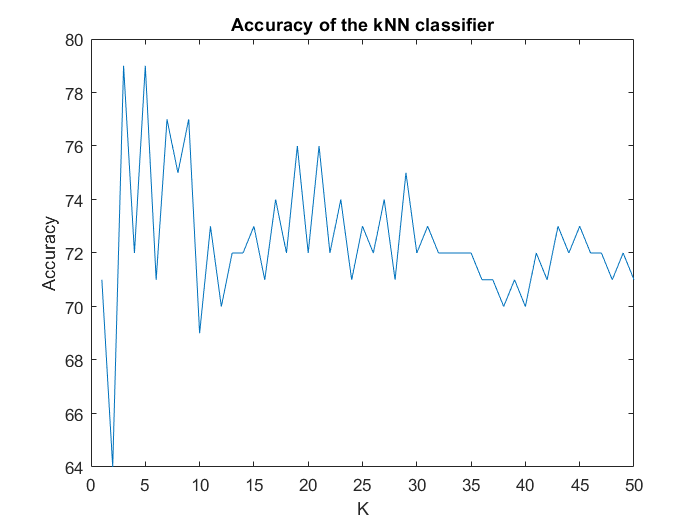

% Choose the classifier to run
classifier = input('Which classifier to run? bayes:1, kNN:2, kernel svm:3, boosted svm:4\n', 's');
analysis_type = input('Which analysis to run? Normal:1, PCA:2, MDA:3\n', 's');

% Perform the user selected analysis
if analysis_type == '1'
    new_train_data = train_data;
    new_test_data = test_data;
    new_dim = dim;
elseif analysis_type == '2'
    [new_train_data, new_test_data, new_dim] = pca(train_data, test_data, dim);
else
    [new_train_data, new_test_data, new_dim] = mda(train_data, test_data, dim);
end

% Use the user selected classifier
if classifier == '1'
   accuracy = bayes_classifier(new_train_data, new_test_data, new_dim, total_classes, len_train_class, len_test, label_test);
elseif classifier == '2'
    acc = zeros(50,1);
    neighbors = 1:50;
    for i=1:50
       acc(i) = knn_classifier(i, new_test_data, new_train_data, label_test, label_train, len_test, len_train);
    end
    plot(neighbors, acc);
    xlabel('K');
    ylabel('Accuracy');
    title('Accuracy of the kNN classifier');
elseif classifier == '3'
    accuracy = kernel_svm();
else
    accuracy = boosted_svm();
end

% disp('Classification accuracy:');
% disp(strcat(num2str(accuracy),'%'));